# Systematic review of SysID - model representations

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Jingxiao Liu
% Inferlab, CEE, CMU
% June, 2019
% This is my first Matlab live script for introducing system 
% identification;
% Some contents are based on Arun K. Tangirala's SysID lecture in IIT
% and the textbook "System identification - an introduction" by Keesman
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Workflow**:

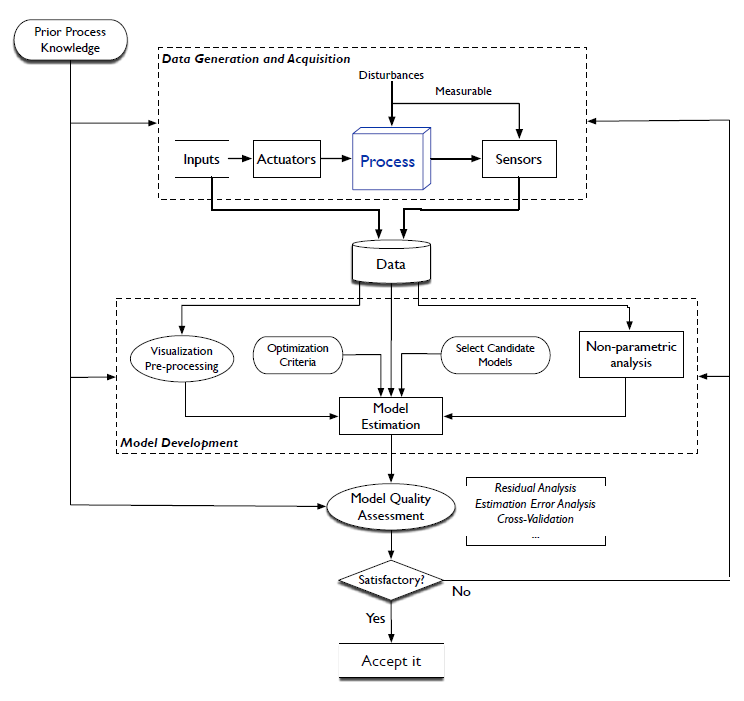

## **First-principles or Empirical**

## **Empirical model: Non-parametric or Parametric; Black-box or Grey-box**

## **LInear or Non-linear**

## **Time-invariant or Time-varying**

## **Single-scale or Multi-scale**

## **Continuous or Discrete**

## **Static or Dynamic**

## **Lumped or Distributed**

## **Deterministic or Stochastic**

**Deterministic model**: the model that explains the effect of physical / measured input(s) on the output(s).

**Stochastic model**: the model which accounts for the unmeasured disturbances and sensor noise

The overall model developed through identification is a composite model. The deterministic model is driven by a physical input while the stochastic portion of the model is driven by a shock wave (fictitious and unpredictable)

A good identification exercise separates the deterministic and stochastic parts with reasonable accuracy.

## **Identifiability**

Identifiability is guaranteed if the data set is sufficiently informatve. It provides the ability to estimate the parameters of a selected model using a given dataset, and to discriminate between two models of different structures.

## Signal-to-Noise Ratio (SNR)

The ratio of variance of signal to the variance of noise in a measurement:


$$\mathrm{SNR}=\frac{{\sigma_{\mathrm{signal}} }^2 }{{\sigma_{\mathrm{noise}} }^2 }$$


Or a measure of the degree of certainty to uncertainty.

## Linear time-invariant system

skip...but one interesting defination is:

A system is linear and time-invariant if and only if a sine wave of frequency $\omega$ input produces a resposne (at steady-state) of the same frequency $\omega$ (does not produce a new frequency reponse).

Since FRF is a function of the input frequency, every LTI system acts as a filter.

## Part 0. Different representations of a dynamic system -- 2-DoF mass-spring-damper system

Define stiffness and mass matrices

|\/\/\/\/\O\/\/\/\/\O

   k1 c1  m1  k2 c2  m2


$$M\ddot{X} +C\dot{X} +\textrm{KX}=F$$


clc;
clear;
close all;
addpath ../functions/
m1=5; %mass 1 [kg]
m2=2; %mass 2 [kg]
k1=200; %spring 1 [N/m]
k2=100; %spring 2 [N/m]
c1=10; % damping coeff 1
c2=10; % damping coeff 2
M=[m1 0;0 m2]; %mass matrix
K=[k1+k2 -k2; -k2 k2]; %stiffness matrix
Damp=[c1+c2 -c2; -c2 c2]; % damping matrix

## 0.1 Differential equation model

Create time-domain signal by differential equation


$$\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\ddot{x} }_1 \\
{\ddot{x} }_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
c_1 +c_2  & -c_2 \\
-c_2  & c_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
k_1 +k_2  & -k_2 \\
{-k}_2  & k_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
F_1 \\
F_2 
\end{array}\right\rbrack$$



$$X\left(t\right)=x_C \left(t\right)+X_P \left(t\right)$$


Solution of the differential equations is sum of the complementary solution and the particular solution.

To obtain the complementary solution, we should solve:


$$M\ddot{X} +C\dot{X} +\textrm{KX}=0$$


The characteristic equation is


$$Mr^2 +\mathit{Cr}+K=0$$


The roots of the characteristic equation are


$$r_{1,2} =\frac{-C\pm \sqrt{C^2 -4\mathit{MK}}}{2M}$$


If $C^2 -4\mathit{MK}=0$, the system is critical damping.

If $C^2 -4\textrm{MK}<0$, the system is under damping.

If $C^2 -4\textrm{MK}>0$, the system is over damping. 

For civil structures, we consider the under-damped case.

Then, $r_{1,2} =-\frac{C}{2M}\pm \frac{\sqrt{C^2 -4\mathit{MK}}}{2M}=-\xi \pm \omega_d i$,


$$x_C \left(t\right)={\mathrm{const}}_1 e^{-\xi t} \mathrm{cos}\left(\omega_d t\right)+{\mathrm{const}}_2 e^{-\xi t} \mathrm{sin}\left(\omega_d t\right)$$


while ${\mathrm{const}}_1 =X\left(0\right),{\mathrm{const}}_2 =\frac{\dot{X} \left(0\right)+\xi X\left(0\right)}{\omega }$

To obtain the particular solution, we just need to assume a form of the particular solution and plug into the differential equations. For example, suppose


$$X_P \left(t\right)=a\;\mathrm{cos}\omega_P t+b\;\mathrm{sin}\omega_P t$$


Then


$$\dot{X_P } \left(t\right)=-a\omega_P \;\mathrm{sin}\omega_P t+b\;\omega_P \mathrm{cos}\omega_P t$$



$$\ddot{X_P } \left(t\right)=-a\omega_P^2 \;\cos \omega_P t-b\omega_P^2 \;\sin \omega_P t$$


Thus,

M($-a\omega_P^2 \;\cos \omega_P t-b\omega_P^2 \;\sin \omega_P t$)+*C*$\left(-a\omega_P \;\sin \omega_P t+b\;\omega_P \cos \omega_P t\right)+K\left(a\;\mathrm{cos}\omega_P t+b\;\mathrm{sin}\omega_P t\right)=F$

Solve the above equation, we will obtain *a *and *b*, then the particular solution.

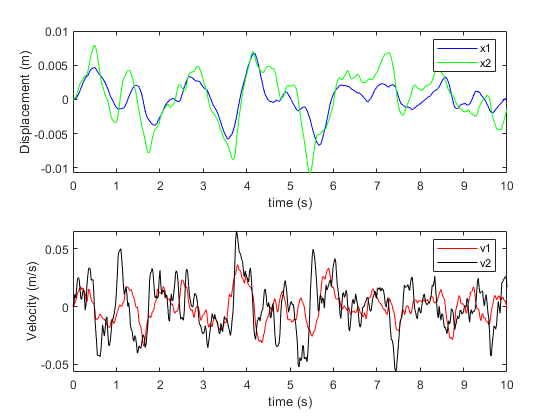

%% Solving system as ODE
T = 10; %length of time duration
nt = 500; %number of time stamps
Fs = nt/T;
tspan=linspace(0,T,nt);
x0=[0;0;0;0]; %initialization of states
rng(49)
F = randn(2,length(tspan)); % input ambient force
% F = zeros(2,length(tspan)); %input force
% hammer = zeros(length(tspan),1);
% hammer(51:80) = 1;
% hammer(251:280) = 1;
% hammer(451:480) = 1;
% F(1,:) = hammer;
% hammer2 = zeros(length(tspan),1);
% hammer2(101:150) = 1;
% hammer2(251:300) = 1;
% F(2,:) = hammer2;
% F(1,:) = 20*sin(10*tspan);
% F(2,:) = 10*sin(5*tspan);
odefun=@(t,y) solve_2dof(t,y,M,Damp,K,tspan,F); %ODE function
[tsol,ysol]=ode45(odefun,tspan,x0); %solve by ODE solver
figure(1)
plot_dv(tsol,ysol) %plot function

## 0.2 State-space model

Create time-domain signal by state-space model

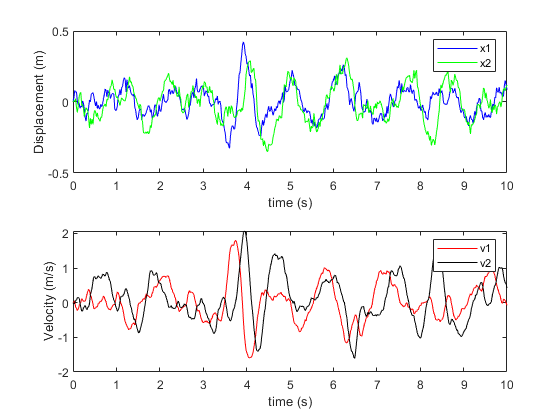

C = [1,0,0,0;
     0,1,0,0;
     0,0,1,0;
     0,0,0,1]; %observation matrix
rs = 94; %random seed with my lucky number
pro_n_l = [0.,0.,1e-6,1e-5,1e-4,1e-3]; %process noise levels
obs_n_l = [0.,1e-4,1e-4,1e-4,1e-4,1e-4]; %observation noise levels
filenames = {'../data/2dof.csv','../data/2dof_noP.csv','../data/2dof_P6.csv','../data/2dof_P5.csv','../data/2dof_P4.csv','../data/2dof_P3.csv'};
promu = [0;0;0;0]; %mean of process noise
obsmu = [0;0;0;0]; %mean of observation noise
% save input
csvwrite('../data/ambient.csv',F)
for i = 1:6
    prosi = pro_n_l(i)*eye(4); %covariance matrix of process noise
    obssi = obs_n_l(i)*eye(4); %covariance matrix of observation noise
    ysol1 = glti_2dofO_generator(m1,m2,k1,k2,c1,c2,T,nt,x0,F,C,...
                                        promu,prosi,obsmu,obssi,rs); %generate data by using gaussian state space model
    % save output
    csvwrite(filenames{i},ysol1)
end
figure(2)
plot_dv(tspan,ysol1')

## 0.3 Impulse function model / frequency response function model / transfer function model

If the input function is a Dirac delta function, the unit-impulse response function is


$$h\left(t\right)=\left\lbrace \begin{array}{cc}
\frac{1}{M\omega_d }e^{-\xi \omega_n t} \;\mathrm{sin}\omega_d t & t>0\\
0 & t<0
\end{array}\right.$$


where $\omega_n =\sqrt{\frac{K}{M}\;}$,

Then apply the Dhamel integral, the impulse response is


$$h\left(t-\tau \right)=\frac{1}{M\omega_d }e^{-\xi \omega_n \left(t-\tau \right)} \mathrm{sin}\left(\omega_d \left(t-\tau \right)\right)$$


Thus,


$$X\left(t\right)=\int_0^t F\left(\tau \right)h\left(t-\tau \right)d\tau$$


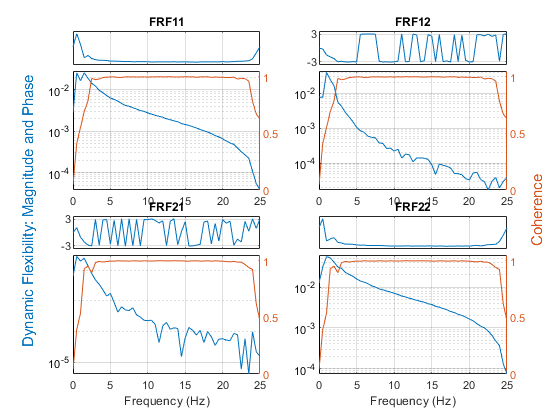

winlen = size(F,2)/5;
figure(4)
modalfrf(F',ysol(:,3:4),Fs,hann(winlen),0.5*winlen,'Sensor','dis');